# **EJERCICIOS EE**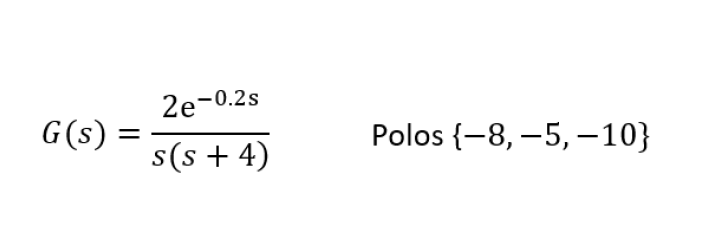

s=tf('s');
G=(2*exp(-0.2*s))/(s*(s+4))
Tk=feedback(G,1)
step(Tk)
stepinfo(Tk)
G=pade(G)
Ge=ss(G) %Para hallar la matriz de espacio de estados
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
order(G)
Mc=rank(ctrb(A,B))

P=[-8 -5 -10]

k=acker(A,B,P)

Alc=A-B*k; %Retroalimentacion
Gc=ss(Alc,B,C,0) %Sistema compensado en ganancia
GC1=tf(Gc) %Pasamos de espacio de estados a TF

F=1/dcgain(Gc) %Precompensador

step(GC1*F) %Aplicamos precompensador
stepinfo(GC1)%Graficamos compensado
